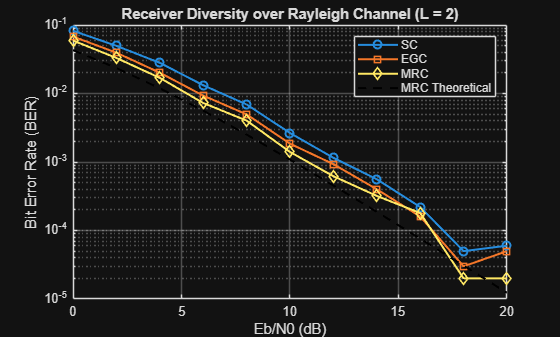

clc; clear; close all;

% Parameters
N = 1e5;                  % Number of bits
EbN0_dB = 0:2:20;         
EbN0 = 10.^(EbN0_dB/10);
L = 2;                    % Number of diversity branches

% Generate bits
bits = randi([0 1], N, 1);
symbols = 2*bits - 1;     % BPSK

% BER arrays
ber_sc  = zeros(size(EbN0));
ber_egc = zeros(size(EbN0));
ber_mrc = zeros(size(EbN0));

for i = 1:length(EbN0)
    
    % Noise
    noise = sqrt(1/(2*EbN0(i))) * ...
        (randn(N,L) + 1j*randn(N,L));
    
    % Rayleigh channel (L branches)
    h = (randn(N,L) + 1j*randn(N,L)) / sqrt(2);
    
    % Transmit over all branches
    tx = repmat(symbols,1,L);
    rx = h .* tx + noise;
    
    %% ================= SC =================
    [~, idx] = max(abs(h), [], 2);  % select best branch
    sc_out = zeros(N,1);
    for k = 1:N
        sc_out(k) = rx(k, idx(k)) / h(k, idx(k));
    end
    bits_hat = real(sc_out) > 0;
    ber_sc(i) = sum(bits ~= bits_hat)/N;
    
    %% ================= EGC =================
    egc_out = sum(rx .* exp(-1j*angle(h)), 2);
    bits_hat = real(egc_out) > 0;
    ber_egc(i) = sum(bits ~= bits_hat)/N;
    
    %% ================= MRC =================
    mrc_out = sum(conj(h) .* rx, 2);
    bits_hat = real(mrc_out) > 0;
    ber_mrc(i) = sum(bits ~= bits_hat)/N;
    
end

%% ================= Theoretical MRC =================
theory_mrc = zeros(size(EbN0));

for i = 1:length(EbN0)
    gamma = EbN0(i);
    theory_mrc(i) = (1/2)*(1 - sqrt(gamma/(1+gamma)))^L;
end

%% ================= Plot =================
figure;
semilogy(EbN0_dB, ber_sc, 'o-', 'LineWidth', 1.5); hold on;
semilogy(EbN0_dB, ber_egc, 's-', 'LineWidth', 1.5);
semilogy(EbN0_dB, ber_mrc, 'd-', 'LineWidth', 1.5);
semilogy(EbN0_dB, theory_mrc, 'k--', 'LineWidth', 1.5);

grid on;
xlabel('Eb/N0 (dB)');
ylabel('Bit Error Rate (BER)');
title(['Receiver Diversity over Rayleigh Channel (L = ', num2str(L), ')']);
legend('SC','EGC','MRC','MRC Theoretical');